# Lab 5

## R1. Maximum Likelihood Estimators

clear;
close all;

## R1.a)

Functions $\texttt{MLEexponential}$,$\texttt{MLErayleigh}$, and $\texttt{MLEnormal}$

## R1.b)

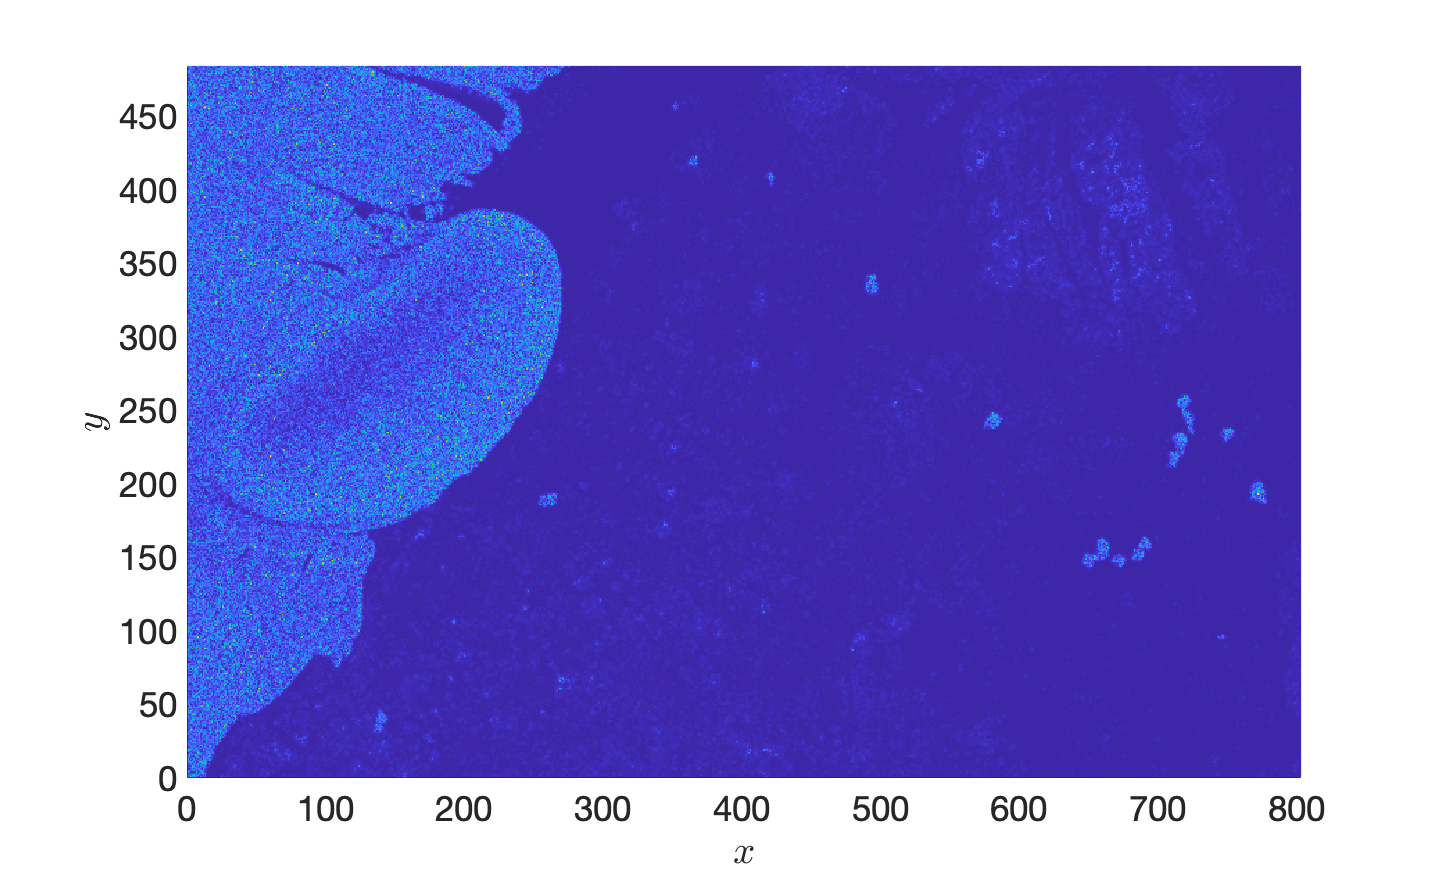

load('sar_image.mat','I'); % Load data
% Visualize image
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$x$",'Interpreter','latex');
ylabel("$y$",'Interpreter','latex');
set(gca,'FontSize',35);
xlim([0 size(I,2)]);
ylim([0 size(I,1)]);
imagesc(I)
saveas(gcf,'./figures/R1b.png');

## R1.c)

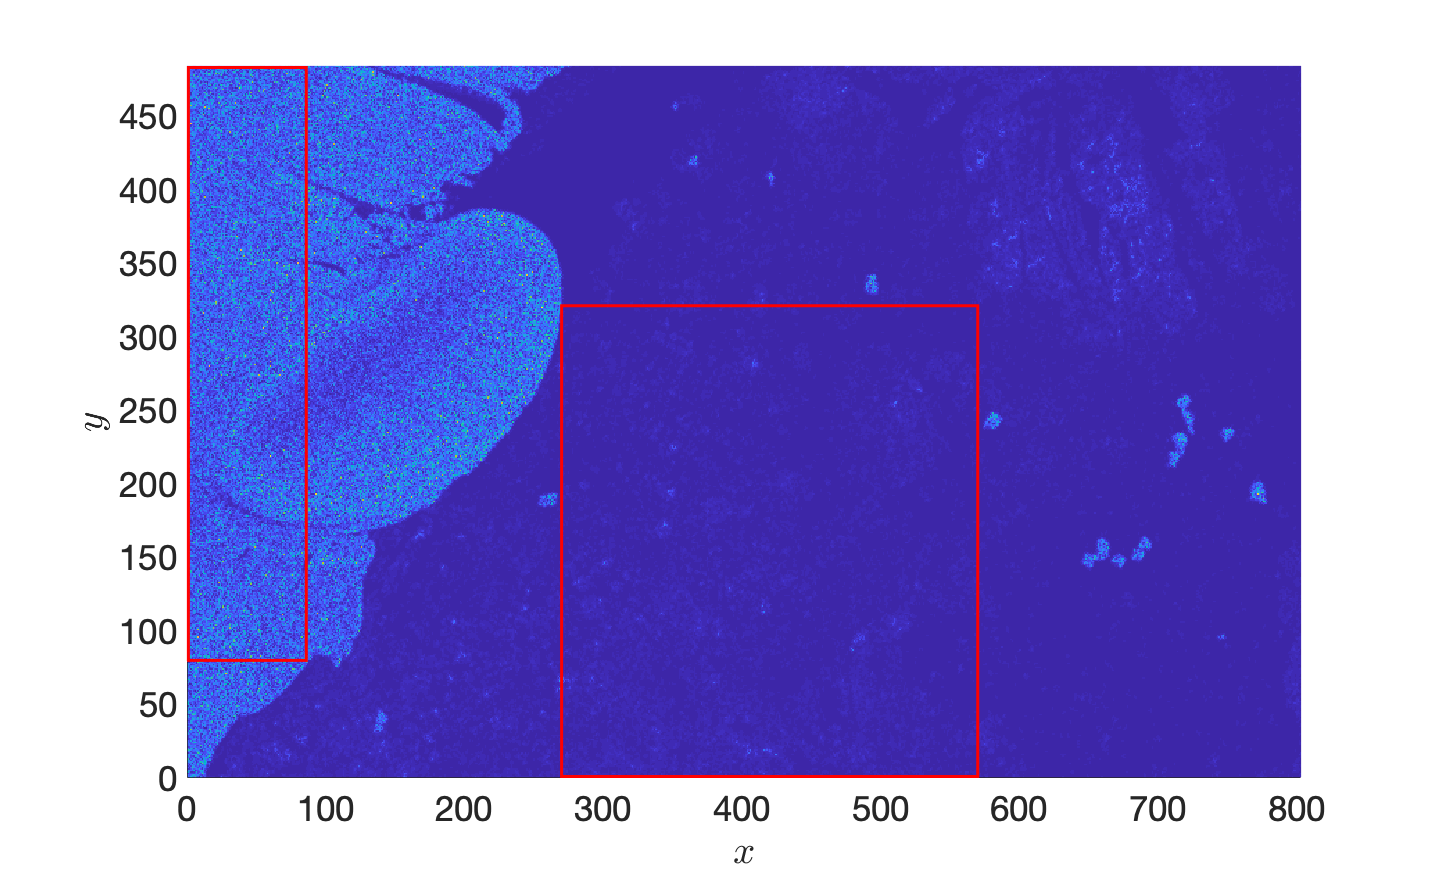

% Fincd crop with:
% [~,rect] = imcrop(I);
% Crop ice 
rectIce = [1 80 85 403];
ice = imcrop(I,rectIce);
ice = ice(:);
rectWater = [270 1 300 320];
water = imcrop(I,rectWater);
water = water(:);
load('sar_image.mat','I'); % Load data
% Visualize image
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$x$",'Interpreter','latex');
ylabel("$y$",'Interpreter','latex');
set(gca,'FontSize',35);
xlim([0 size(I,2)]);
ylim([0 size(I,1)]);
imagesc(I)
rectangle('Position',rectIce,'EdgeColor','r','LineWidth',3);
rectangle('Position',rectWater,'EdgeColor','r','LineWidth',3);
saveas(gcf,'./figures/R1c.png');

% Ice
ice_lambda_ML = MLEexponential(ice)

ice_lambda_ML = 7.7559e+04

ice_f_ML = MLErayleigh(ice)

ice_f_ML = 6.4909e+04

[ice_mu_ML, ice_var_ML] = MLEnormal(ice)

ice_mu_ML = 7.7559e+04

ice_var_ML = 2.4111e+09

% Water
water_lambda_ML = MLEexponential(water)

water_lambda_ML = 5.6263e+03

water_f_ML = MLErayleigh(water)

water_f_ML = 4.9659e+03

[water_mu_ML, water_var_ML] = MLEnormal(water)

water_mu_ML = 5.6263e+03

water_var_ML = 1.7665e+07

## R1.d)

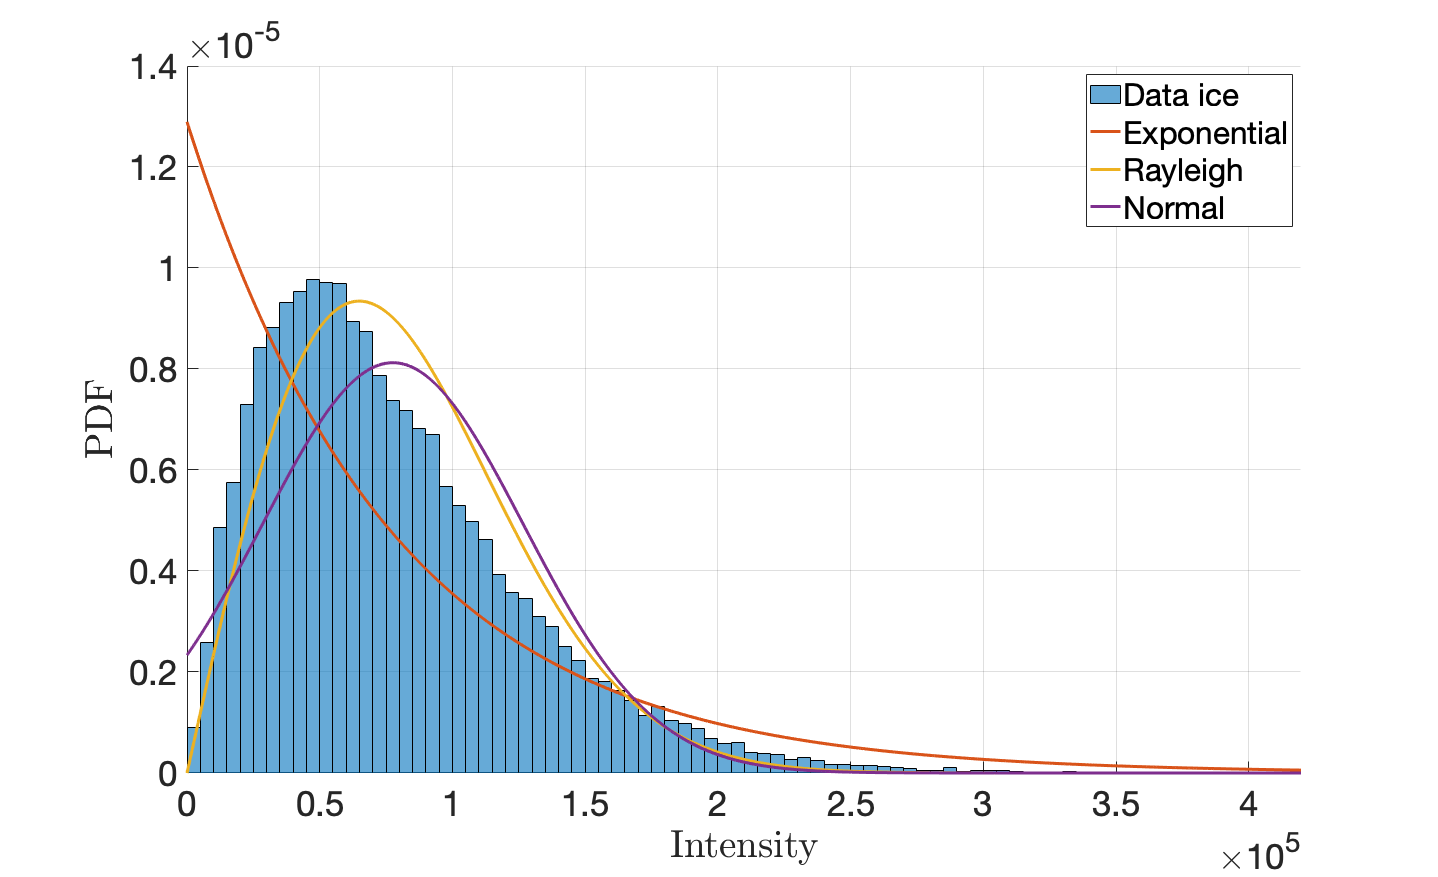

% Ice
x = 0:1:max(max(I));
ice_exp = exppdf(x,ice_lambda_ML);
ice_rayleigh = raylpdf(x,ice_f_ML);
ice_norm = normpdf(x,ice_mu_ML,sqrt(ice_var_ML));

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("Intensity",'Interpreter','latex');
ylabel("PDF",'Interpreter','latex');
set(gca,'FontSize',35);
histogram(ice, 'Normalization', 'pdf');
plot(x,ice_exp,'LineWidth',3);
plot(x,ice_rayleigh,'LineWidth',3);
plot(x,ice_norm,'LineWidth',3);
xlim([0 max(max(I))]);
legend('Data ice','Exponential','Rayleigh','Normal');
saveas(gcf,'./figures/R1d_ice.png');

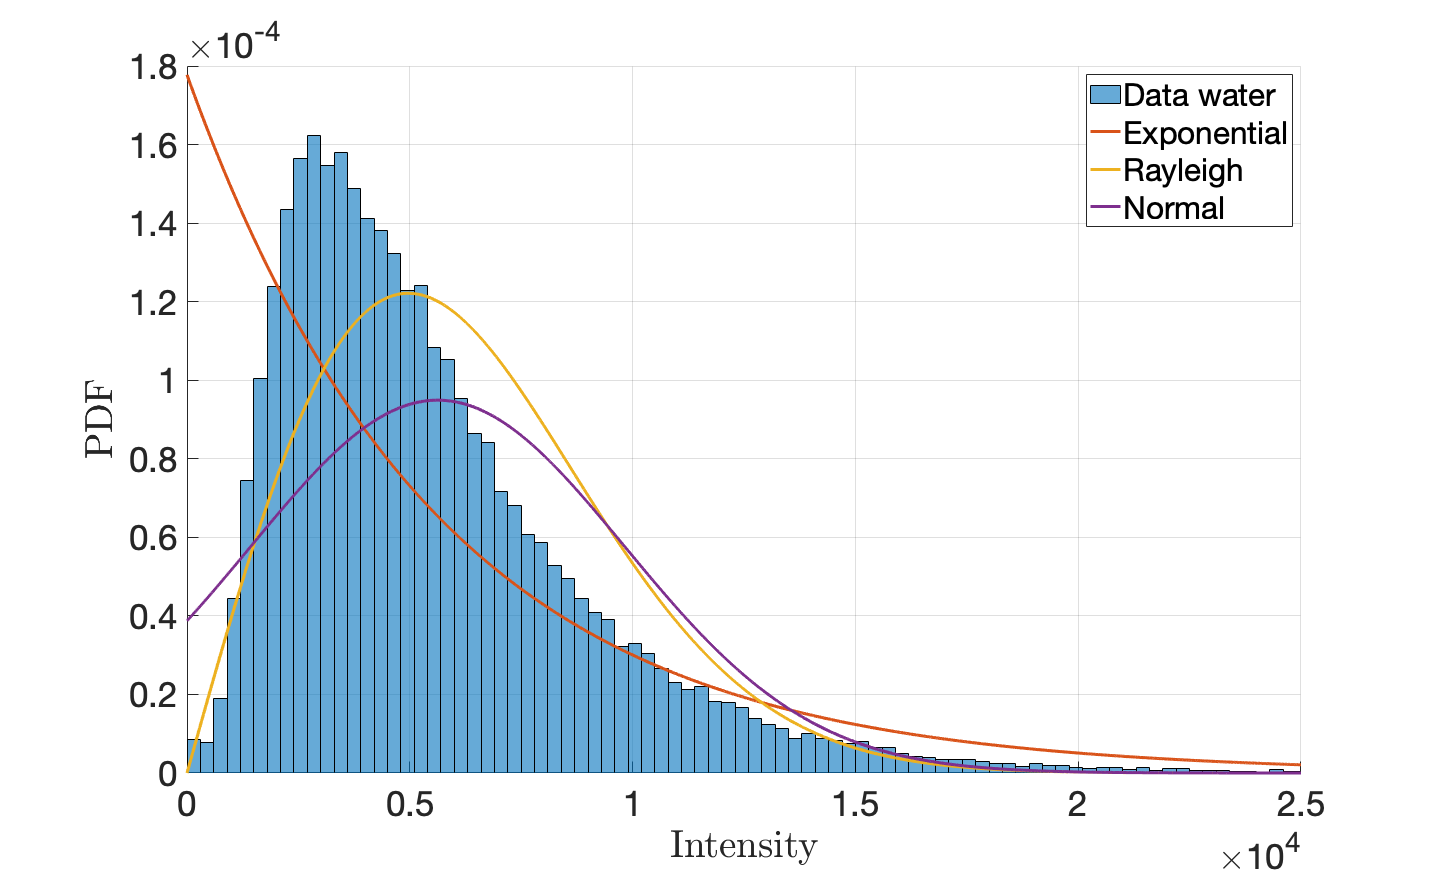


% Water
x = 0:1:2.5e4;
water_exp = exppdf(x,water_lambda_ML);
water_rayleigh = raylpdf(x,water_f_ML);
water_norm = normpdf(x,water_mu_ML,sqrt(water_var_ML));

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("Intensity",'Interpreter','latex');
ylabel("PDF",'Interpreter','latex');
set(gca,'FontSize',35);
histogram(water, 'Normalization', 'pdf');
plot(x,water_exp,'LineWidth',3);
plot(x,water_rayleigh,'LineWidth',3);
plot(x,water_norm,'LineWidth',3);
xlim([0 2.5e4]);
legend('Data water','Exponential','Rayleigh','Normal');
saveas(gcf,'./figures/R1d_water.png');

## R2. a)

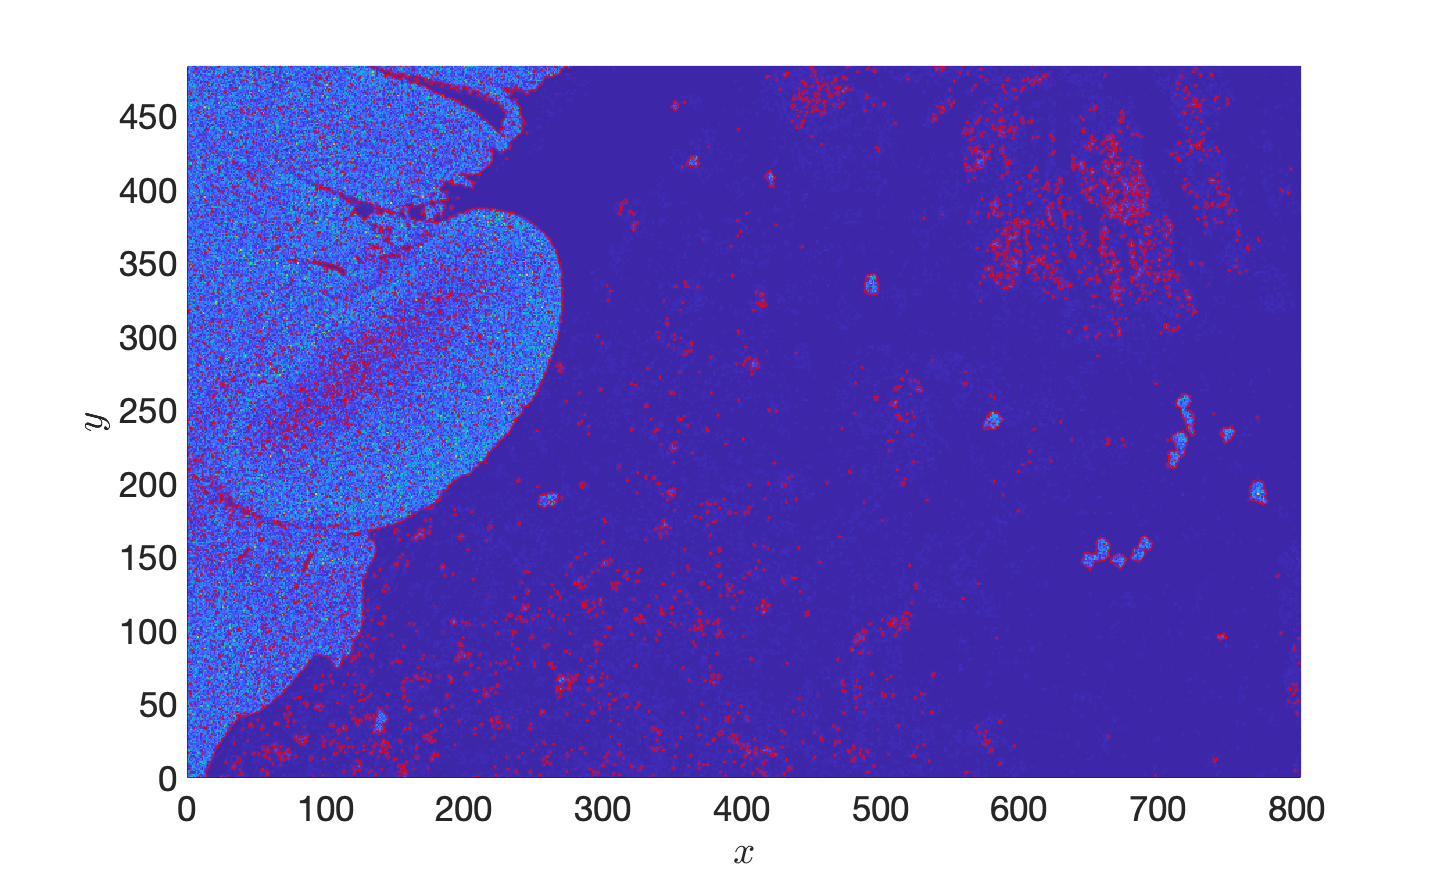

% Compute log likelihood
ice_llikelihood = log(raylpdf(I,ice_f_ML));
water_llikelihood = log(raylpdf(I,water_f_ML));
% Compute classification
classification_a = zeros(size(I));
for i = 1:size(I,1)
    for j = 1:size(I,2)
        if(water_llikelihood(i,j) >= ice_llikelihood(i,j))
            classification_a(i,j) = 1;
        end
    end
end

% Visualize classification
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$x$",'Interpreter','latex');
ylabel("$y$",'Interpreter','latex');
set(gca,'FontSize',35);
xlim([0 size(I,2)]);
ylim([0 size(I,1)]);
imagesc(I);
imcontour(classification_a,1,'r');
saveas(gcf,'./figures/R2a.png');

## R2.b)

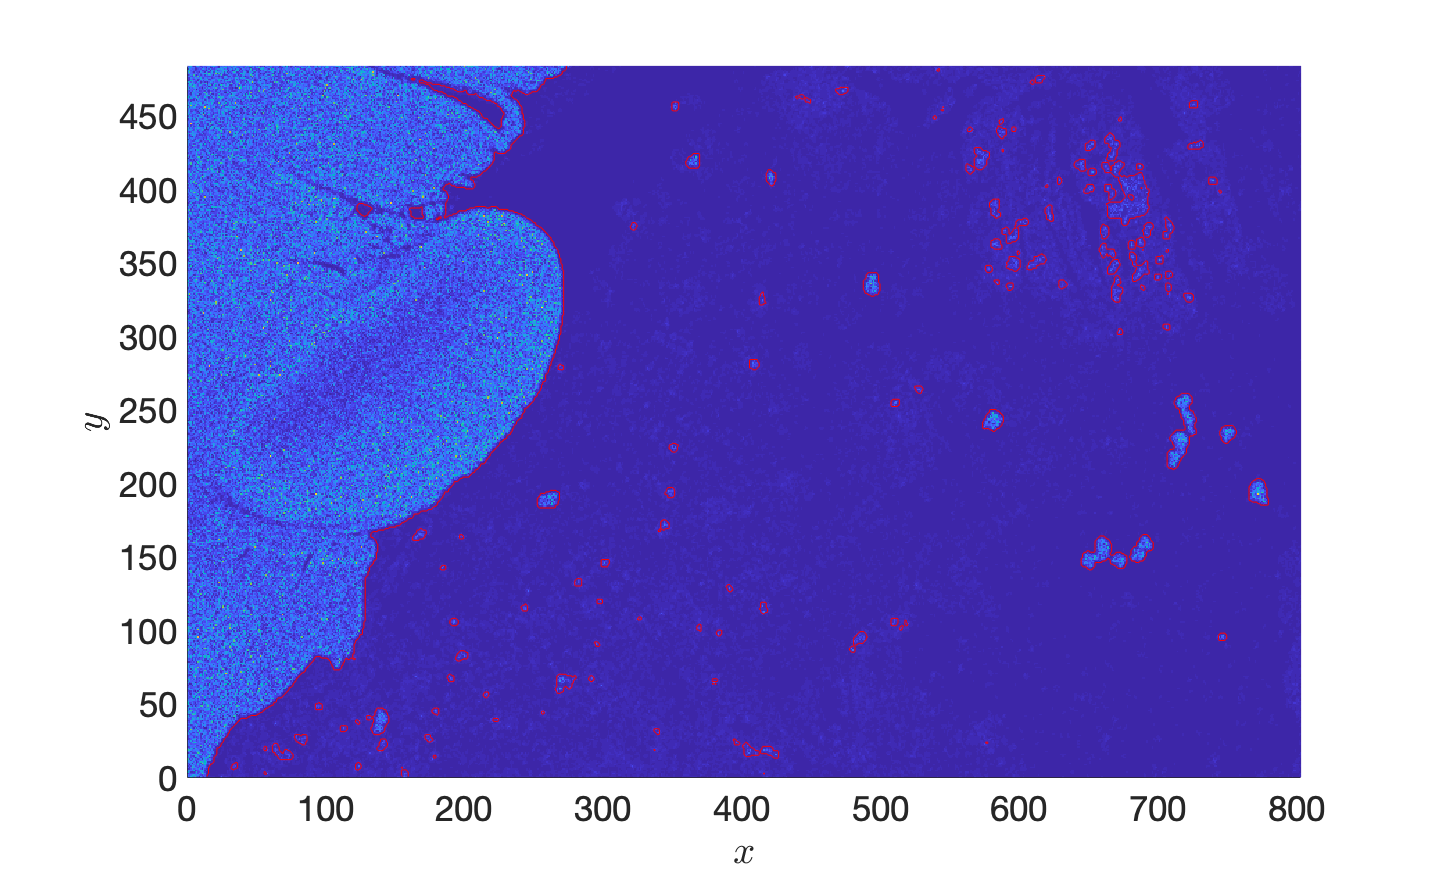

% Filter 
kernel = (1/25)*ones(5);
I_filt = conv2(I,kernel,'same');
% Compute log likelihood
ice_llikelihood_filt = log(raylpdf(I_filt,ice_f_ML));
water_llikelihood_filt = log(raylpdf(I_filt,water_f_ML));
% Compute classification
classification_b = zeros(size(I));
for i = 1:size(I,1)
    for j = 1:size(I,2)
        if(water_llikelihood_filt(i,j) >= ice_llikelihood_filt(i,j))
            classification_b(i,j) = 1;
        end
    end
end

% Visualize classification
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$x$",'Interpreter','latex');
ylabel("$y$",'Interpreter','latex');
set(gca,'FontSize',35);
xlim([0 size(I,2)]);
ylim([0 size(I,1)]);
imagesc(I);
imcontour(classification_b,1,'r');
saveas(gcf,'./figures/R2b.png');

## R2.c)

% R1.a)
% Ice
classification_a_ice = imcrop(classification_a,rectIce);
a_ice_rate = 1-sum(sum(classification_a_ice))/(size(classification_a_ice,1)*size(classification_a_ice,2))

a_ice_rate = 0.9526

% Water
classification_a_water = imcrop(classification_a,rectWater);
a_water_rate = sum(sum(classification_a_water))/(size(classification_a_water,1)*size(classification_a_water,2))

a_water_rate = 0.9811

% R1.b)
% Ice
classification_b_ice = imcrop(classification_b,rectIce);
b_ice_rate = 1-sum(sum(classification_b_ice))/(size(classification_b_ice,1)*size(classification_b_ice,2))

b_ice_rate = 1

% Water
classification_b_water = imcrop(classification_b,rectWater);
b_water_rate = sum(sum(classification_b_water))/(size(classification_b_water,1)*size(classification_b_water,2))

b_water_rate = 0.9921